此示例展示一个简单的数据筛选、PCA作图的流程。

首先载入UniExp数据库

UETables=load(MATLAB.UITools.OpenFileDialog(Filter='UniExp数据库|*UniExp.mat',Title='选择UniExp数据库'));

如果不同回合具有不同的采样率，但真实时间相同，则需要进行重采样一致化。

UETables.TrialSignals.TrialSignal=UniExp.SampleNormalize(UETables.TrialSignals.TrialSignal);

这里假定重采样后所有数据采样率为30。如果不是，根据实际情况调整。

采样率单位/s，可根据DateTimes表中的SeriesInterval(㎳)求得。SampleRate=1000/SeriesInterval

SampleRate=30;

列出每条PCA线的筛选条件，可多选合并数据，留空表示该条件不做限制。其中：

SessionIndex指示某种设计的会话的时间次序，如，BlueAudioWater会话的第1次

LineConditions={
	%Design				SessionIndex	Stimulus
	"BlueOnlyWater"		1				"BlueOnly"
	"BlueOnlyWater"		2				"BlueOnly"
	"AudioOnlyWater"	1				"AudioOnly"
};
LineTable=table('Size',[height(LineConditions),3],'VariableTypes',repmat("cell",1,3),'VariableNames',["Design","SessionIndex","Stimulus"]);
LineTable{:,:}=LineConditions;

可选限制要使用的鼠、细胞类型和Z层，以及要输出的主成分个数。

UniExp.Normalize为枚举类，列出支持的归一化算法。默认不归一化。如果需要归一化，还必须指定F0Samples。F0Sampes表示标准化过程中要作为基线的回合时点，通常应为1:刺激前秒数×采样率。

[PcaLines,Explained,Coeff,CellUID]=UniExp.LinearPca(UETables,LineTable,UniExp.Normalize.log2FdF0,1:SampleRate*2,CellType="All",ZLayer="L2",NumComponents=3);

Starting parallel pool (parpool) using the 'Threads' profile ...
Connected to the parallel pool (number of workers: 3).


PcaLines是元胞列向量，每个元胞对应LineConditions表的一行，表示一条线。元胞内是数值矩阵，表示线上按时间顺序的每个点的主成分分数，第1维是时间，第2维是主成分。后续可以据此作图。

作图。首先生成优化的颜色配置：

Colors=GlobalOptimization.ColorAllocate(height(LineConditions),[1 1 1])

GlobalSearch stopped because it analyzed all the trial points.

All 98 local solver runs converged with a positive local solver exit flag.


Colors =     1.0000    0.0000    1.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000


图例文本：

LegendText=[
	"BlueOnlyWater.1.BlueOnly"
	"BlueOnlyWater.2.BlueOnly"
	"AudioOnlyWater.1.AudioOnly"
	"0s"
	"3s"
	"5s"
];

关键时点突出显示：

KeyIndex=[0,3,5]*SampleRate+1;

关键时点符号

KeyMarkers='o^s';

作图

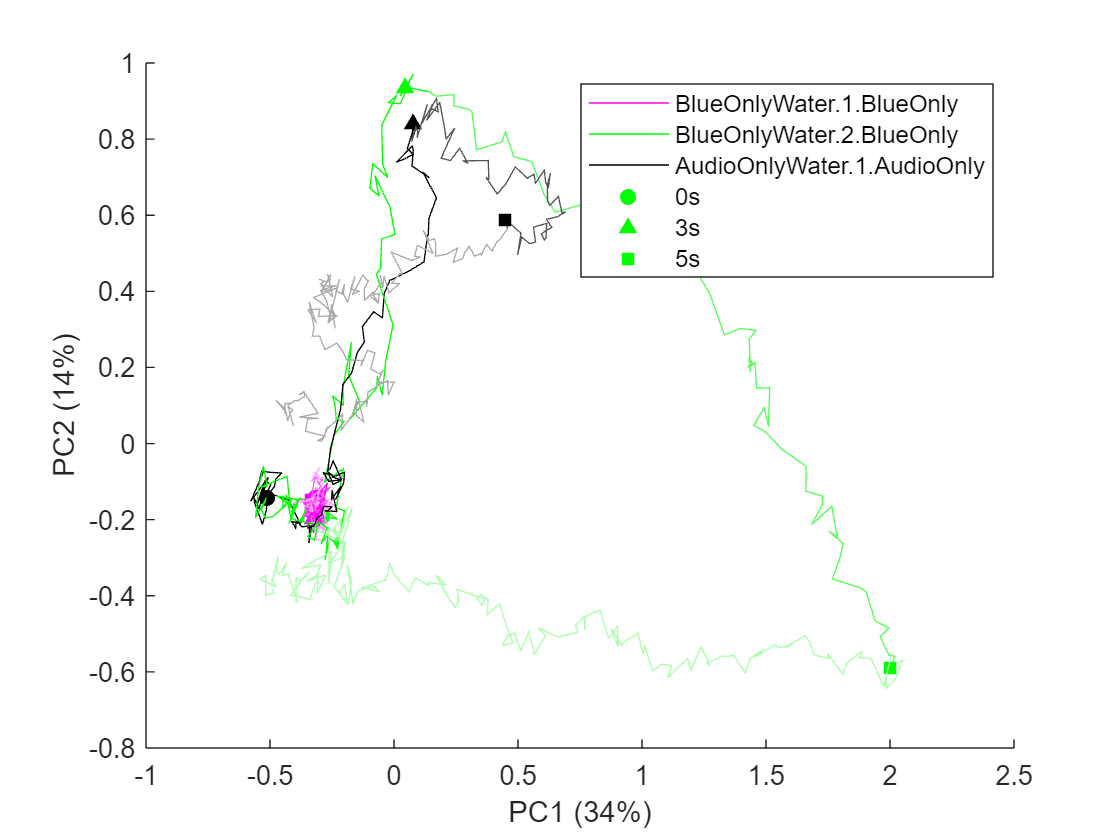

figure;
[Lines,Scatters]=UniExp.SegmentFadePlot(permute(cat(3,PcaLines{:}),[1,3,2]),Colors,KeyIndex,KeyMarkers);
legend(vertcat(Lines,Scatters),LegendText);
xlabel(sprintf('PC1 (%.2g%%)',Explained(1)));
ylabel(sprintf('PC2 (%.2g%%)',Explained(2)));
zlabel(sprintf('PC3 (%.2g%%)',Explained(3)));